# Filtr antyaliasingowy

fs = 256e3; % podobnie jak pasmo
fstop = 128e3;

%filtersMatrix = 
[a1,b1] = butter(4,0.5,'s');
[a2,b2] = cheby1(4,3,0.5,'s');
[a3,b3] = cheby2(4,3,0.5,'s');
[a4,b4] = ellip(4,3,40,0.5,'s');
%[ab(1,1),ab(1,2)]
filtersMatrix(1,:)=freqs(a1,b1,fs);
filtersMatrix(2,:)=freqs(a2,b2,fs);
filtersMatrix(3,:)=freqs(a3,b3,fs);
filtersMatrix(4,:)=freqs(a4,b4,fs);

skala 0:1

norma = 0:1/fs:1-1/fs;

skala 0:fs

norma = 0:fs-1;

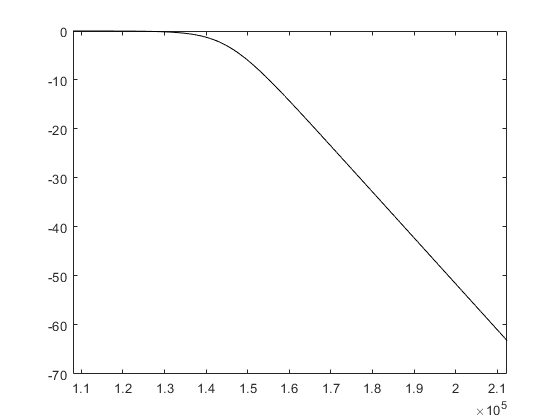

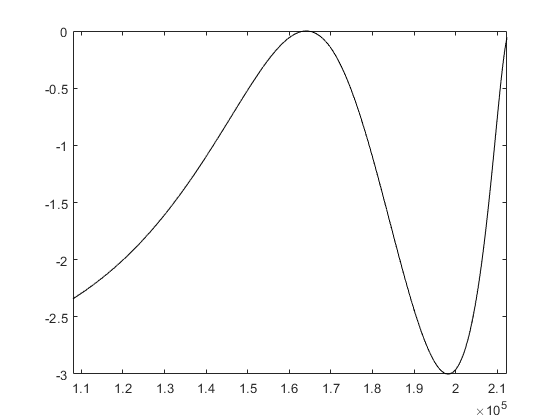

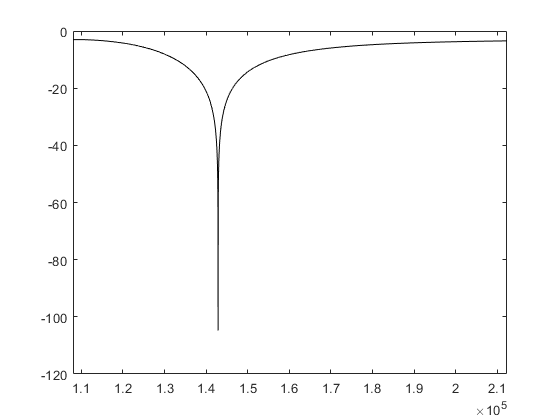

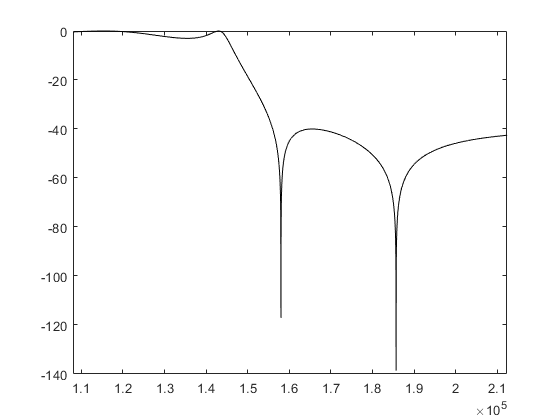

 
for i=1:size(filtersMatrix,1)
    figure
    plot(norma,20*log10((filtersMatrix(i,:))),'k')
    xlim([107980 212358])
    %fvtool(filtersMatrix(i,:),'FrequencyRange','[-pi, pi)','Color','White');
end